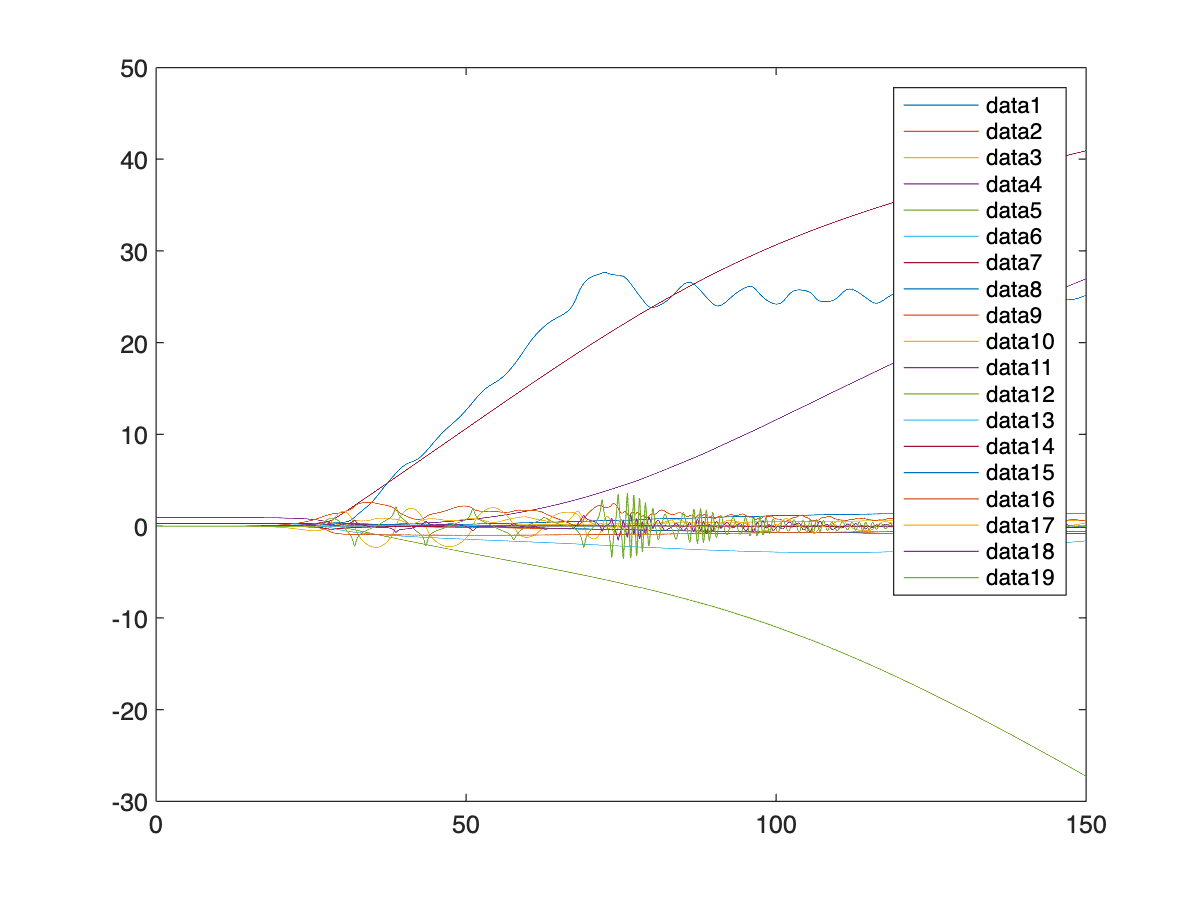

clear
filename='SC_3DoF.urdf';
[robot, robot_keys]=urdf2robot(filename);
n=robot.n_links_joints;
n_q=robot.n_q;
%initial conditions
r_0=zeros(3,1);
qm0=zeros(n_q,1);
T0 = axang2tform([0 1 1 pi/4])*trvec2tform([0 0 0]);
quat_0=tform2quat(T0);
% final conditions
r_final = [1 1 1];
TF = axang2tform([1 0 1 6*pi/5])*trvec2tform(r_final);

tStep=0.01;
tMin=0;
tMax=150; %for ODE45
tInterval = [tMin tMax];
tvec = tMin:tStep:tMax;

%time scaling to smooth the trajectory
%maybe add boundary conditions here
[s,sd,sdd] = minjerkpolytraj([0 1],tInterval,numel(tvec));
[tfInterp1,v1,a1] = transformtraj(T0,TF,tInterval,tvec,TimeScaling=[s; sd; sdd]);
rotations = tform2quat(tfInterp1); % Scalar-first quaternions
translations = tform2trvec(tfInterp1);
v_0=v1(:,1);
qmdot_0 = zeros(n_q,1);

z0=[r_0; %3 (1:3)
    quat_0'; %4 (4:7)
    qm0; %n_q (3) (8:10)
    v_0; %6 (11:16)        
    qmdot_0]; %n_q (17:19)  

%Set up the integration 
[tSol,zSol]=ode45(@(t,z) SPARTFun(t,z, translations, rotations, v1, a1, tMin, tStep), tInterval, z0);
plot(tSol, zSol)
legend(Location="bestoutside")

plot(tSol, zSol(:,4:7))


function zDot = SPARTFun(t,z, translations, rotations, v1, a1, tMin, tStep)
kp = 10; kd = 10;
filename='SC_3DoF.urdf';
[robot, robot_keys]=urdf2robot(filename);
n=robot.n_links_joints;
n_q=robot.n_q;

r_cm=z(1:3);

quat_cm=z(4:7); %normalize
quat_cm=quat_cm/norm(quat_cm);
etaE=quat_cm(1); %scalar-first
epsilonE=quat_cm(2:4);

qm = z(8:7+n_q);
v_cm = z(8+n_q:10+n_q);
omega_cm = z(11+n_q:13+n_q);
qmdot=z(14+n_q:end);

[zDe, aDe] = trajectory(t, translations, rotations, v1, a1, tMin, tStep, n_q);

rD=zDe(1:3);

rotD=zDe(4:7);
etaD=rotD(1);
epsilonD=rotD(2:4);

qmD = zDe(8:7+n_q);
vD = zDe(8+n_q:10+n_q);
omegaD= zDe(11+n_q:13+n_q);
qmdotD=zDe(14+n_q:end);
err_r = rD-r_cm;

err_quat = etaE*epsilonD - etaD*epsilonE -vCross(epsilonD)*epsilonE;

err_v = vD - v_cm;
err_om = omegaD - omega_cm;
err_qm = qmD -  qm;
err_qmdot = qmdotD-qmdot;

R0 = quat2rotm(quat_cm');
r0 = r_cm;

[RJ,RL,rJ,rL,e,g]=Kinematics(R0,r0,qm,robot);
[Bij,Bi0,P0,pm]=DiffKinematics(R0,r0,rL,e,g,robot);

u0=[omega_cm;v_cm]; %angular;linear (not my notation)
um = qmdot;
[t0,tL]=Velocities(Bij,Bi0,P0,pm,u0,um,robot);

%Inertias projected in the inertial frame
[I0,Im]=I_I(R0,RL,robot);
%Mass Composite Body matrix
%[M0_tilde,Mm_tilde]=MCB(I0,Im,Bij,Bi0,robot);
%Generalized Inertia Matrix
%[H0, H0m, Hm] = GIM(M0_tilde,Mm_tilde,Bij,Bi0,P0,pm,robot);
%Generalized Convective Inertia Matrix
%[C0, C0m, Cm0, Cm] = CIM(t0,tL,I0,Im,M0_tilde,Mm_tilde,Bij,Bi0,P0,pm,robot);

%as previously find forces using PD control 
f0 = kp*err_r + kd*err_v;
n0 = kp*err_quat + kd*err_om; 
tau = kp*err_qm + kd*err_qmdot;

wF0 = zeros(6,1); %external wrench
wFm = zeros(6, n_q); %external wrench
tau0 = [n0;f0]; %base generalized force
%taum = tau;
taum=zeros(robot.n_q,1);

% well it doesn't work anyway this sucks

%[u0dot_FD,umdot_FD] = FD(tau0,taum,wF0,wFm,t0,tL,P0,pm,I0,Im,Bij,Bi0,u0,um,robot);
%quaternion kinematics first - check this
epsilon_dot=1/2*(vCross(epsilonE) + etaE*eye(3))*omega_cm;
eta_dot = -1/2*(epsilonE')*omega_cm;
%zDot = [u0dot_FD(4:6); u0dot_FD(1:3); umdot_FD];

wF0=zeros(6,1);
%wF0(6)=-robot.base_link.mass*g;
wFm=zeros(6,robot.n_links_joints);
%for i=1:robot.n_links_joints
%        wFm(6,i)=-robot.links(i).mass*g;
%end

%Forward dynamics
[u0dot_FD,umdot_FD] = FD(tau0,taum,wF0,wFm,t0,tL,P0,pm,I0,Im,Bij,Bi0,u0,um,robot);


%here, "forward dynamics" finds the motion given a set of applied forces
%and "inverse dynamics" finds the forces required to produce the given
%motions
%define accelerations for inverse dynamics
%u0dot = [a1(4:6); a1(1:3)]; % desired base accelerations
%umdot = zeros(n_q, 1);
%[t0dot,tLdot]=Accelerations(t0,tL,P0,pm,Bi0,Bij,u0,um,u0dot,umdot,robot)
zDot=[v_cm;epsilon_dot;eta_dot;qmdot;u0dot_FD(4:6);u0dot_FD(1:3);umdot_FD];
end

function [zDe, aDe] = trajectory(t, translations, rotations, v1, a1, tMin, tStep, n_q)

%Base trajectory
maxA=1;
i = floorDiv((t-tMin), tStep)+1;
r=mod((t-tMin), tStep);
ps=translations(i,:);
qs=quaternion(rotations(i,:));
if i<=15000
    pf=translations(i+1,:);
    qf=quaternion(rotations(i+1,:));
v_i=v1(:,i); %linear; angular velocity
a_i=v1(:,i); %linear; angular acceleration
v_f=v1(:,i+1); %linear; angular velocity
a_f=a1(:,i+1); %linear; angular acceleration

rot = slerp(qs,qf,r); % slerp interpolate orientation
rot=compact(rot);
tr = ps + (pf - ps)*r; % linear interpolate position 
v =  v_i + (v_f - v_i)*r; % linear interpolate velocity
a =  a_i + (a_f - a_i)*r; % linear interpolate acceleration
else
    tr=ps;
    rot=rotations(i,:);
    v=v1(:,i);
    a=v1(:,i);
end
%Manipulator trajectory - extend each joint in turn

if t>n_q*44-1
    qS=zeros(n_q,1);
    qSdot=zeros(n_q,1);
else  
    t_t=mod(t,44);
    j=floorDiv(t,44)+1;
    qS=zeros(n_q,1);
    qSdot=zeros(n_q,1);
    
        if t_t<=10
            qSdot(j)=maxA;
            qS(j)=maxA*t_t;
        elseif t_t<=12
            qSdot(j)=0.0;
            qS(j)=maxA*10;
        elseif t_t<=32
            qSdot(j)=-maxA;
            qS(j)=maxA*10+qSdot(j)*(t_t-12);
        elseif t_t<=34
            qSdot(j)=0.0;
            qS(j)=-maxA*10.0;
        else
            qSdot(j)=maxA;
            qS(j)=-maxA*10+qSdot(j)*(t_t-34);
        end
   %qSdot
end
zDe=[tr';
    rot';
    qS;
    v;
    qSdot];
aDe = a;
end